clc
clear

% Loading image
image_path = 'CROP1_47.tiff';
hcube = imread(image_path);
load("testGT.mat")

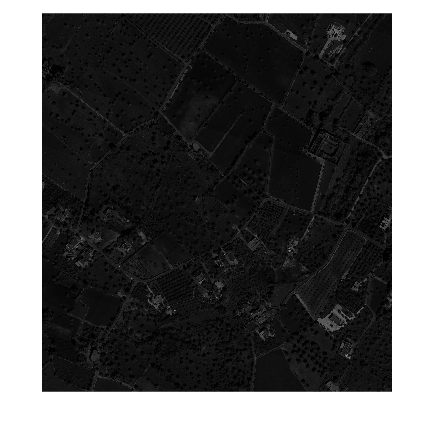

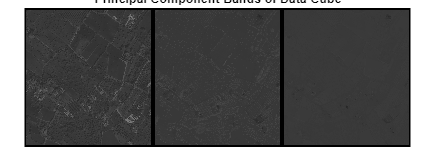

% Calculating PCA
[image,components] = PCA(hcube,5);

% Reshaping image
pixels = reshape(image, [], size(image, 3));

% Define your class labels here. This should be a vector of the same length as the number of pixels.
labels = idx;

% Split data into training and testing sets
rng('default'); % For reproducibility
c = cvpartition(labels,'HoldOut',0.3); % Hold out 30% of the data for testing
pixelsTrain = pixels(training(c),:);
labelsTrain = labels(training(c),:);

% Random Forest training
numTrees = 500; % Increase the number of trees
RFmodel = TreeBagger(numTrees, pixelsTrain, labelsTrain, 'Method', 'classification', 'OOBPrediction', 'on');

% Predict classes on all data
[idx_rf,scores] = predict(RFmodel, pixels);

% Convert cell array of predictions to matrix
idx_rf = cellfun(@str2double, idx_rf);

% Calculate accuracy on all data
accuracy = sum(labels == idx_rf) / length(labels);

% Print accuracy
fprintf('Accuracy of the model is %f\n', accuracy);

% Obtaining image's sizes
[rows, cols, ~] = size(image);

image = reshape(idx_rf, [rows, cols]);

% Plot results
figure;
imshow(reshape(idx_rf, [rows, cols]), []);
colormap(jet(max(idx_rf))); % Use the maximum cluster label to define the colormap range
colorbar;
title('Random Forest classification results');
